## Configuration Analysis for a Novel Control Law for 3 Link Manipulator

% define all the system variables
syms delta_1 delta_2 delta_3 phi_1 phi_2 phi_3 alpha R l D_11 D_12 D_13 D_21 D_22 D_23 D_31 D_32 D_33

% Compute deltas through geometric analysis
delta_1 = alpha - atan2((sin(phi_1)+sin(phi_1+phi_2)+sin(phi_1+phi_2+phi_3)),(cos(phi_1)+cos(phi_1+phi_2)+cos(phi_1+phi_2+phi_3)))

$$delta\_1 = \alpha -\text{atan2}\left(\sin\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\sin\left(\varphi_{1}+\varphi_{2}\right)+\sin\left(\varphi_{1}\right),\cos\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\cos\left(\varphi_{1}+\varphi_{2}\right)+\cos\left(\varphi_{1}\right)\right)$$

delta_2 = atan2((R*sin(alpha)-l*sin(phi_1)),(R*cos(alpha)-l*cos(phi_1))) - atan2((sin(phi_1+phi_2)+sin(phi_1+phi_2+phi_3)),(cos(phi_1+phi_2)+cos(phi_1+phi_2+phi_3)))

$$delta\_2 = \text{atan2}\left(R\,\sin\left(\alpha \right)-l\,\sin\left(\varphi_{1}\right),R\,\cos\left(\alpha \right)-l\,\cos\left(\varphi_{1}\right)\right)-\text{atan2}\left(\sin\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\sin\left(\varphi_{1}+\varphi_{2}\right),\cos\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\cos\left(\varphi_{1}+\varphi_{2}\right)\right)$$

delta_3 = atan2((R*sin(alpha)-2*l*sin(phi_1+phi_2/2)*cos(phi_2/2)),(R*cos(alpha)-2*l*cos(phi_1+phi_2/2)*cos(phi_2/2))) - (phi_1+phi_2+phi_3)

$$delta\_3 = -\varphi_{1}-\varphi_{2}-\varphi_{3}+\text{atan2}\left(R\,\sin\left(\alpha \right)-2\,l\,\sin\left(\varphi_{1}+\frac{\varphi_{2}}{2}\right)\,\cos\left(\frac{\varphi_{2}}{2}\right),R\,\cos\left(\alpha \right)-2\,l\,\cos\left(\varphi_{1}+\frac{\varphi_{2}}{2}\right)\,\cos\left(\frac{\varphi_{2}}{2}\right)\right)$$

alpha_val = 0;
R_val = 2.1;
l_val = 1.2;
num_roots = 10;
accumulated_roots = 0;
tested_roots = 0;
roots = zeros(num_roots,3);
while accumulated_roots < num_roots
    phi_1_val = rand()*2*pi-pi;
    phi_2_val = rand()*2*pi-pi;
    phi_3_val = rand()*2*pi-pi;
    deltas = double(subs([delta_1,delta_2,delta_3],[phi_1,phi_2,phi_3,alpha,R,l],[phi_1_val,phi_2_val,phi_3_val,alpha_val,R_val,l_val]));
    tested_roots = tested_roots + 1;
    if all(deltas<1e-7)
        accumulated_roots = accumulated_roots + 1;
        roots(accumulated_roots,1) = phi_1_val;
        roots(accumulated_roots,2) = phi_2_val;
        roots(accumulated_roots,3) = phi_3_val;
        disp(accumulated_roots)
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



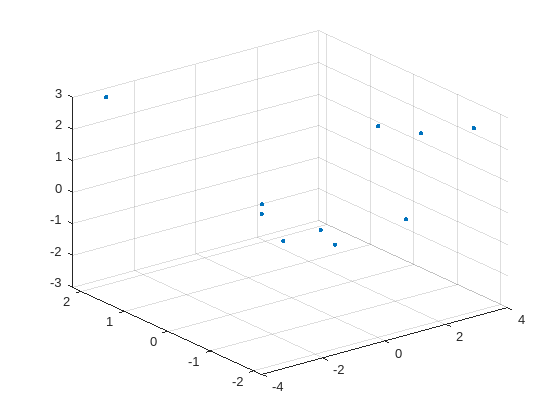

A = roots;
scatter3(A(:,1),A(:,2),A(:,3),'.');

f1 = matlabFunction((subs(delta_1, [R,l,alpha], [2.1,1,pi/6])))

f1 = function_handle with value:
    @(phi_1,phi_2,phi_3)pi./6.0-atan2(sin(phi_1+phi_2+phi_3)+sin(phi_1+phi_2)+sin(phi_1),cos(phi_1+phi_2+phi_3)+cos(phi_1+phi_2)+cos(phi_1))


f2 = matlabFunction((subs(delta_2, [R,l,alpha], [2.1,1,pi/6])))

f2 = function_handle with value:
    @(phi_1,phi_2,phi_3)-atan2(sin(phi_1+phi_2+phi_3)+sin(phi_1+phi_2),cos(phi_1+phi_2+phi_3)+cos(phi_1+phi_2))+atan2(-sin(phi_1)+2.1e+1./2.0e+1,-cos(phi_1)+sqrt(3.0).*(2.1e+1./2.0e+1))


f3 = matlabFunction((subs(delta_3, [R,l,alpha], [2.1,1,pi/6])))

f3 = function_handle with value:
    @(phi_1,phi_2,phi_3)-phi_1-phi_2-phi_3+atan2(sin(phi_1+phi_2./2.0).*cos(phi_2./2.0).*-2.0+2.1e+1./2.0e+1,sqrt(3.0).*(2.1e+1./2.0e+1)-cos(phi_1+phi_2./2.0).*cos(phi_2./2.0).*2.0)


[x, y, z] = meshgrid(linspace(-pi, pi, 50), linspace(-pi, pi, 50), linspace(-pi, pi, 50));
% Evaluate the functions at each point
values_f1 = f1(x, y, z);
values_f2 = f2(x, y, z);
values_f3 = f3(x, y, z);

% Find points where all three functions are zero
zero_points = (abs(values_f1) < 1e-4) & (abs(values_f2) < 1e-4) & (abs(values_f3) < 1e-4);
zero_x = x(zero_points);
zero_y = y(zero_points);
zero_z = z(zero_points);